clc; clear;

N = 400;
net = IzhikevichNetwork(400, 'BaseFolder', fullfile("Data", "TrainingProcedure"));
net.stimulation = true; net.STDP = true;
stim = Stimulation(net, 100, 2, 30, 50, 5);
net.sampling_rate = 1000;
net.run(100 * 1000);
data = net.getData();
firings = data.firings;

# Raster plot of trials

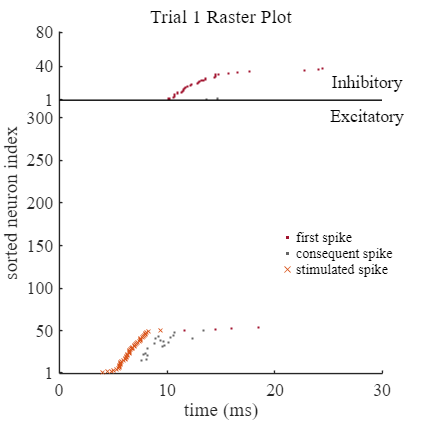

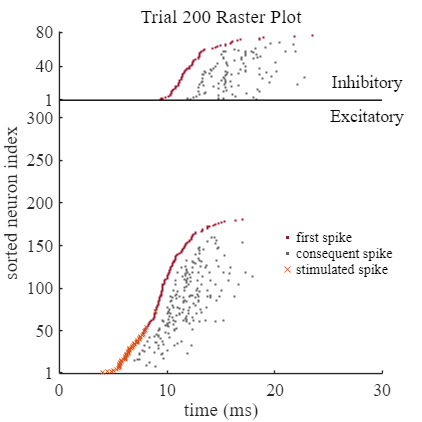

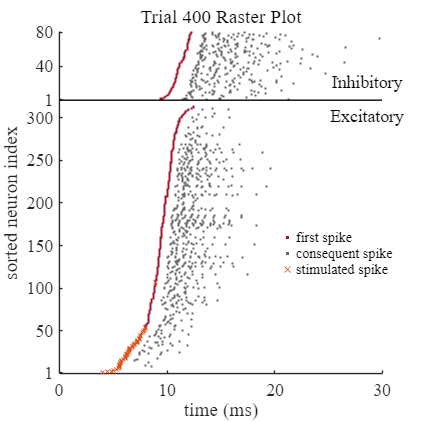

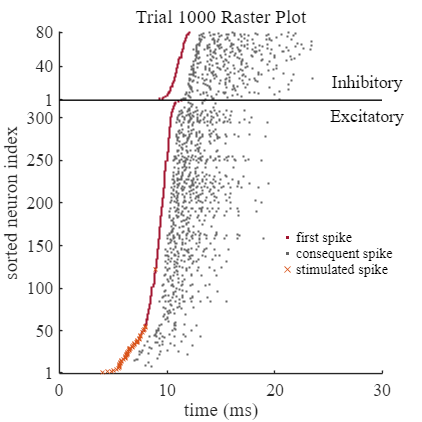

fsize = 12;
msize = 15;

firings = transpose(data.firings);
interval = net.stims(1).interval;

% orange color [0.8500 0.3250 0.0980]
stim_color = [0.8500 0.3250 0.0980];
first_color = [0.6350 0.0780 0.1840];
repeated_color = [0.4 0.4 0.4];

for trial_number = [1, 200, 400, 1000]

    check_flag = zeros(1, net.N);
    
    indices = (firings(:, 1) > (trial_number-1) * interval) & (firings(:, 1) <= trial_number * interval);
    spike_times = firings(indices, 1) - (trial_number-1)*interval;
    neuron_indices = firings(indices, 2);
    
    counter_ex = 1;
    counter_inh = net.Ne+1;
    
    c_code = zeros(size(spike_times, 1), 3);
    neuron_sorted_indices = zeros(size(spike_times, 1), 1);
    clear h1 h2
    for i = 1:length(spike_times)
        if true
            if neuron_indices(i) <= net.Ne
                if check_flag(neuron_indices(i)) == 0 % First excitatory spikes
                    neuron_sorted_indices(i) = counter_ex;
                    if ismember(neuron_indices(i), stim.pattern_indices)
                        c_code(i, :) = stim_color;
                    else
                        c_code(i, :) = first_color;
                    end

                    check_flag(neuron_indices(i)) = counter_ex;
                    counter_ex = counter_ex + 1;
                else % Repeated excitatory spikes
                    neuron_sorted_indices(i) = check_flag(neuron_indices(i));
                    c_code(i, :) = repeated_color;
                end
            else
                if check_flag(neuron_indices(i)) == 0 % First Inhibitory spikes
                    neuron_sorted_indices(i) = counter_inh;
                    c_code(i, :) = first_color;
    
                    check_flag(neuron_indices(i)) = counter_inh;
                    counter_inh = counter_inh + 1;
                else % Repeated Inhibitory spikes
                    neuron_sorted_indices(i) = check_flag(neuron_indices(i));
                    c_code(i, :) = repeated_color;
  
                end
            end
        end
    end

    fig = figure('Units', 'inches', 'Position', [1 1 4 4]); 
    hold on;

    % Dummy scatter plots for legend only (do NOT plot real data here)
    % Create dummy scatter plots just for legend
    scatter(0, 800, 2000, first_color, '.', 'DisplayName', 'first spike');
    scatter(0, 800, 2000, repeated_color, '.', 'DisplayName', 'consequent spike');
    scatter(0, 800, 2000, stim_color, 'x', 'DisplayName', 'stimulated spike');
    
    colors = [first_color; repeated_color; stim_color];
    markers = ['.', '.', "x"];
    msizes = msize*[1 ,1, 1]; 
    for i = 1:size(colors, 1)
        indices =  ismember(c_code, colors(i, :), 'rows');
        if ~isempty(spike_times(indices))
            scatter(spike_times(indices), neuron_sorted_indices(indices), msizes(i), colors(i, :),'Marker', markers(i), HandleVisibility='off');
        else
           scatter(nan, neuron_sorted_indices(indices), msizes(i), colors(i, :),'Marker', markers(i), HandleVisibility='off');
        end
    end 

    xlabel('time (ms)');
    ylabel('sorted neuron index');
    title(sprintf('Trial %d Raster Plot', trial_number) ,'FontWeight','normal', 'FontName', 'Times New Roman');
    plot([0, 2*interval], (net.Ne + 0.5)*[1, 1], 'k-', HandleVisibility='off')
    xlim([0, 30])
    ylim([0, net.N + 0.5])

    % Add arrows or lines to span the phases at the bottom of the plot
    y_starts = [0.75, 0.83];
    y_ends = [0.85, 0.93];
    phases = ["Excitatory", "Inhibitory"];
    for i = 1:length(phases)
        % annotation('line',[0.81 0.81], [y_starts(i), y_ends(i)], 'Color', 'Black', 'LineWidth', 1, LineStyle='-'); % Stimulation
        annotation('textbox', [0.82,  y_starts(i)/2 + y_ends(i)/2 - 0.05, 0.1, 0.01], 'String', phases(i), 'FontName', 'Times New Roman', 'FontSize', fsize, 'HorizontalAlignment', 'center', 'FontWeight', 'normal', 'EdgeColor', 'none', Rotation=0)
    end
    
    yticks([1, 50:50:300, 321, 360,400])
    yticklabels([1, 50:50:300, 1, 40,80])
    legend('Location', 'east', ...
       'FontSize', 0.8*fsize, ...
       'Box', 'off', 'Position', [0.8, 0.4, 0, 0]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', fsize, 'FontWeight', 'normal'); 
    exportgraphics(fig, sprintf("Trial%d.pdf", trial_number), ContentType="vector")
end

# Extracting weights 

g = data.w; Ex_mask = 1:net.Ne; Inh_mask = net.Ne+1:net.N;
g_ee = g(Ex_mask, Ex_mask, :);
g_ei = g(Ex_mask, Inh_mask, :);
g_ie = g(Inh_mask, Ex_mask, :);

% Get logical adjacency submatrices
adj_ee = net.Adjacency_matrix(Ex_mask, Ex_mask);
adj_ei = net.Adjacency_matrix(Ex_mask, Inh_mask);
adj_ie = net.Adjacency_matrix(Inh_mask, Ex_mask);

% Find linear indices of non-zero connections
[idx_ee_row, idx_ee_col] = find(adj_ee);
[idx_ei_row, idx_ei_col] = find(adj_ei);
[idx_ie_row, idx_ie_col] = find(adj_ie);

% Preallocate output arrays: (connections x time)
T = size(g, 3);  % time dimension
g_ee_masked = zeros(length(idx_ee_row), T);
g_ei_masked = zeros(length(idx_ei_row), T);
g_ie_masked = zeros(length(idx_ie_row), T);

% Extract masked values for all time
for t = 1:T
    tmp_ee = g_ee(:, :, t);
    tmp_ei = g_ei(:, :, t);
    tmp_ie = g_ie(:, :, t);
    g_ee_masked(:, t) = tmp_ee(sub2ind(size(tmp_ee), idx_ee_row, idx_ee_col));
    g_ei_masked(:, t) = tmp_ei(sub2ind(size(tmp_ei), idx_ei_row, idx_ei_col));
    g_ie_masked(:, t) = tmp_ie(sub2ind(size(tmp_ie), idx_ie_row, idx_ie_col));
end

g_ee = g_ee_masked; g_ei = g_ei_masked; g_ie = g_ie_masked;

# simple mean and CI evolution of weights in time\

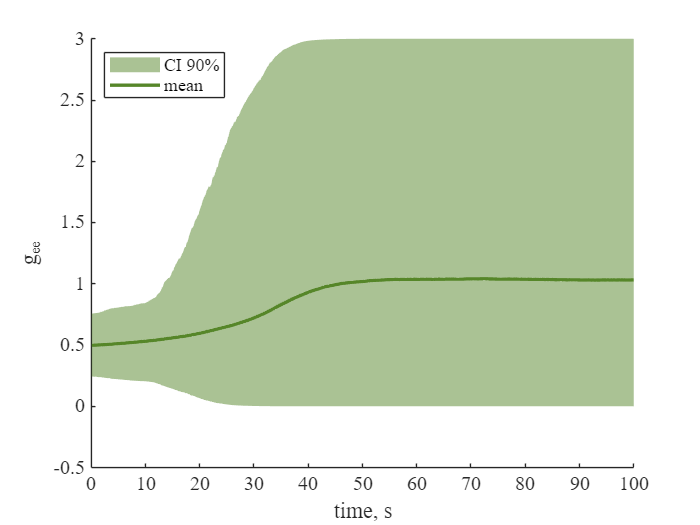

figure; hold on;
fill([1:1000, 1000:-1:1] ,[prctile(g_ee, 95, 1), fliplr(prctile(g_ee, 5, 1))], [86, 135, 41]/256, EdgeColor="none", FaceAlpha=0.5, DisplayName="CI 90%")
plot(mean(g_ee, 1), Color=[86, 135, 41]/256, LineWidth=2, DisplayName="mean");
legend(Location="northwest");
xticks(0:100:1000);
xticklabels((0:100:1000)*0.1);
xlabel("time, s"); ylabel("g_{ee}");

set(gca, 'FontSize', 12, 'fontName', 'Times New Roman')

# Heatmap Evolution of Weights in time

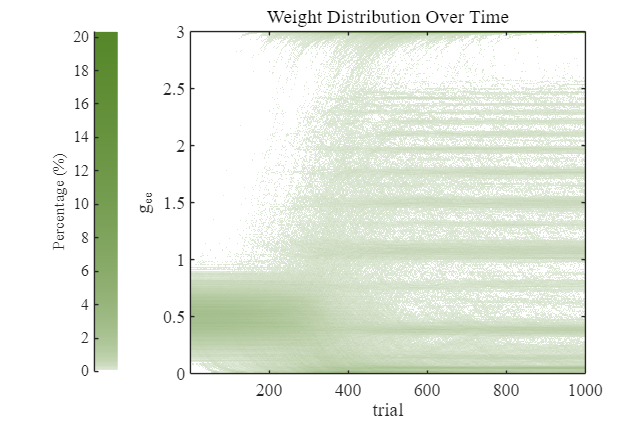

% Binning setup
edges = 0:0.01:3;
bin_centers = edges(1:end-1) + diff(edges(1:2))/2;
time = (1:size(g_ee, 2));  % e.g., if dt = 0.1s
histmat = zeros(length(edges)-1, length(time));

for t = 1:length(time)
    histmat(:, t) = histcounts(g_ee(:, t), edges, 'Normalization', 'percentage');
end

% Create figure with exact size
fig = figure('Units', 'inches', 'Position', [1 1 6 4]);  % [x, y, width, height]

% Plot heatmap
imagesc(time, bin_centers, histmat);
axis xy;
xlabel('trial');
ylabel('g_{ee}');
title('Weight Distribution Over Time', 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight','normal');

% Custom green colormap with gamma correction
gamma = 0.3;
n_colors = 256;
scale = linspace(0, 1, n_colors) .^ gamma;

green_rgb = [86, 135, 41] / 256;
green_cmap = [ ...
    (1 - scale') + scale' * green_rgb(1), ...
    (1 - scale') + scale' * green_rgb(2), ...
    (1 - scale') + scale' * green_rgb(3)];
colormap(green_cmap);

% Colorbar
cb = colorbar('Location', 'westoutside', 'Box','off');
ylabel(cb, 'Percentage (%)');

set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)

% Export with vector quality and consistent dimensions
exportgraphics(fig, "TimeEvolutionOfWeights.pdf", ...
    'ContentType', 'vector', ...
    'Resolution', 300);

# Final Distrubution of Weights

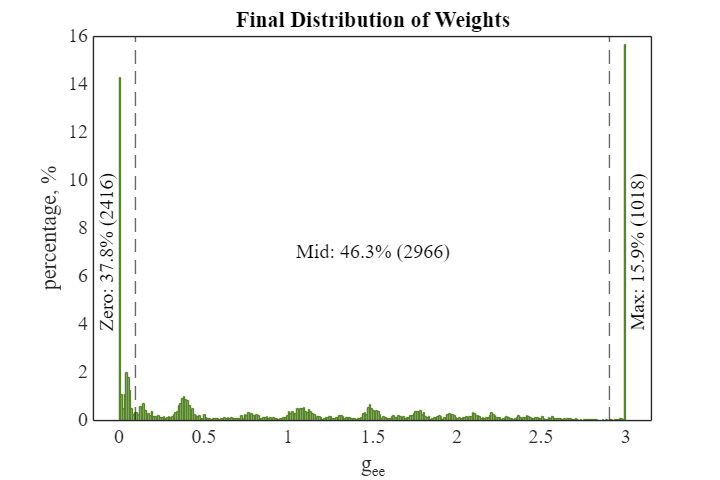

g_ee_final = g_ee(:, end);

% Thresholds
low_thresh = 0.1;
high_thresh = 2.9;

% Counts
N = numel(g_ee_final);
n_zero = sum(g_ee_final < low_thresh);
n_max = sum(g_ee_final > high_thresh);
n_mid = N - n_zero - n_max;

% Percentages
p_zero = 100 * n_zero / N;
p_max  = 100 * n_max / N;
p_mid  = 100 * n_mid / N;


% Plot
fig = figure('Units', 'inches', 'Position', [1 1 6 4]);  % [x, y, width, height]
edges = 0:0.01:3;
histogram(g_ee_final, 'BinEdges', edges, ...
    'Normalization', 'percentage', ...
    'FaceColor', [86, 135, 41]/256, ...
    'EdgeColor', [86, 135, 41]/256);
xlabel("g_{ee}");
ylabel("percentage, %");
title("Final Distribution of Weights", 'FontName', 'Times New Roman', 'FontSize', 12);

% Annotate
xline(low_thresh, LineStyle="--"); xline(high_thresh, LineStyle="--"); y0 = 7;
text(-0.07, y0, sprintf('Zero: %.1f%% (%d)', p_zero, n_zero), "Rotation", 90, "HorizontalAlignment", "center");
text(1.5, y0, sprintf('Mid: %.1f%% (%d)', p_mid, n_mid), "Rotation", 0, "HorizontalAlignment", "center");
text(3.07, y0, sprintf('Max: %.1f%% (%d)', p_max, n_max), "Rotation", 90, "HorizontalAlignment", "center");
ax = gca;  % get current axes
ax.TickLength = [0 0];
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)
exportgraphics(fig, "FinalWeightsDistribution.pdf", ...
    'ContentType', 'vector', ...
    'Resolution', 300);

# Both Previous plots together for the thesis

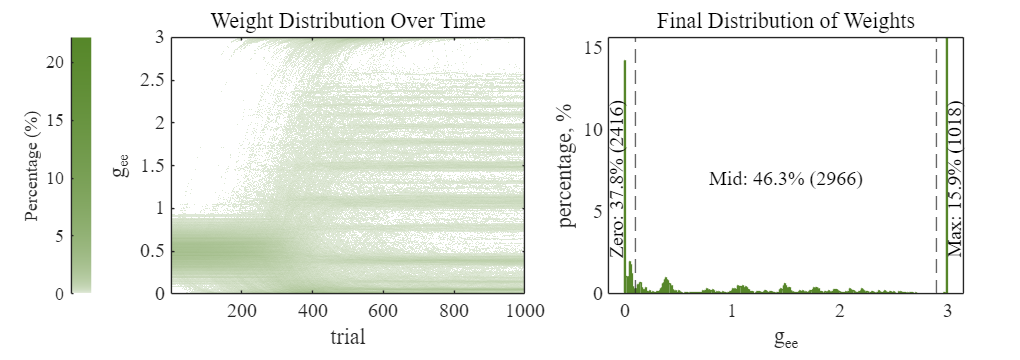

fig = figure('Units', 'inches', 'Position', [1 1 8.5 3]);  % full figure width

tiledlayout(1,2,'TileSpacing','compact','Padding','compact');

% === LEFT PLOT: heatmap with colorbar ===
nexttile;
% Plot heatmap
imagesc(time, bin_centers, histmat);
axis xy;
xlabel('trial');
ylabel('g_{ee}');
title('Weight Distribution Over Time', 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight','normal');

colormap(green_cmap);

% Colorbar
cb = colorbar('Location', 'westoutside', 'Box','off');
ylabel(cb, 'Percentage (%)');

yticks(0:0.5:3)
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)

% === RIGHT PLOT: histogram ===
nexttile;

% Plot
edges = 0:0.01:3;
histogram(g_ee_final, 'BinEdges', edges, ...
    'Normalization', 'percentage', ...
    'FaceColor', [86, 135, 41]/256, ...
    'EdgeColor', [86, 135, 41]/256);
xlabel("g_{ee}");
ylabel("percentage, %");
title("Final Distribution of Weights", 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight','normal');

% Annotate
xline(low_thresh, LineStyle="--"); xline(high_thresh, LineStyle="--"); y0 = 7;
text(-0.07, y0, sprintf('Zero: %.1f%% (%d)', p_zero, n_zero), "Rotation", 90, "HorizontalAlignment", "center");
text(1.5, y0, sprintf('Mid: %.1f%% (%d)', p_mid, n_mid), "Rotation", 0, "HorizontalAlignment", "center");
text(3.07, y0, sprintf('Max: %.1f%% (%d)', p_max, n_max), "Rotation", 90, "HorizontalAlignment", "center");
ax = gca;  % get current axes
ax.TickLength = [0 0];
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)
% EXPORT
exportgraphics(fig, 'Figure_gee_distribution_panel.pdf', 'ContentType', 'vector');

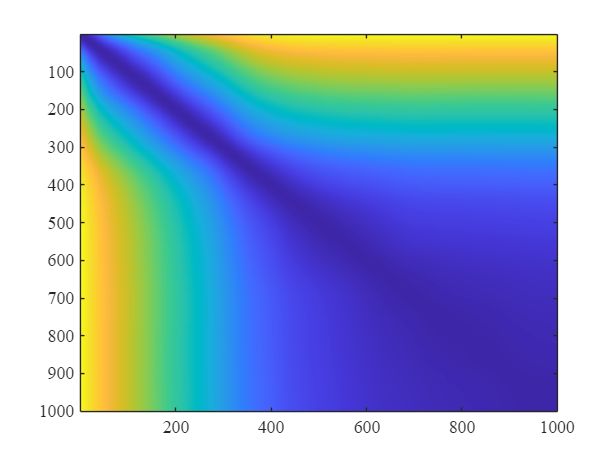

dmat = squareform(pdist(g_ee', 'correlation'));
figure; imagesc(dmat)